% Re-plot 3 Bragg curves on top of each other
clear; close all; clc;

% File directories for each .mat file per condition
Raw.fileDir     = "/Users/andrewsias_m3p/Library/CloudStorage/OneDrive-UCB-O365/Holography/Experiment Data/Holography Experiments/AS_2024_11_06_01/Raw/REPORTS/AO-GH1023-1103-S2 E8 Raw.mat";
Optical.fileDir = "/Users/andrewsias_m3p/Library/CloudStorage/OneDrive-UCB-O365/Holography/Experiment Data/Holography Experiments/AS_2024_11_06_01/Optical Cure/REPORTS/AO-GH1023-1103-S2 E8 Opitcal Cure.mat";
Thermal.fileDir = "/Users/andrewsias_m3p/Library/CloudStorage/OneDrive-UCB-O365/Holography/Experiment Data/Holography Experiments/AS_2024_11_06_02/Thermal Cure/REPORTS/AO-GH1023-1103-S2 E8 Thermal Cure.mat";

% Plot title
plotTitle = "Bragg Detuning Curve of Transmission Hologram";

% Load the data files
Raw.Data     = load(Raw.fileDir);
Optical.Data = load(Optical.fileDir);
Thermal.Data = load(Thermal.fileDir);

% Define paper colors
colorBlock = [0                   0                  0                  ; % Black
              0.33725490196078434 0.7058823529411765 0.9137254901960784 ; % Blue
              0.90196078431372550 0.6235294117647059 0.0000000000000000]; % Gold

% Some data re-formatting
angleMat    = {Raw.Data.OUT.DATA.angleVec;
               Optical.Data.OUT.DATA.angleVec;
               Thermal.Data.OUT.DATA.angleVec};

detuningMat = {Raw.Data.OUT.DATA.detuningVec;
               Optical.Data.OUT.DATA.detuningVec;
               Thermal.Data.OUT.DATA.detuningVec};

% Add readout values to output for referencing
fprintf('Uncured: n1 = %f x 10^-3, L = %f um.\n',Raw.Data.OUT.CWT.out.n1*10^3,Raw.Data.OUT.CWT.out.L*10^6);

Uncured: n1 = 6.118250 x 10^-3, L = 44.786718 um.


fprintf('Optical Cure: n1 = %f x 10^-3, L = %f um.\n',Optical.Data.OUT.CWT.out.n1*10^3,Optical.Data.OUT.CWT.out.L*10^6);

Optical Cure: n1 = 5.786294 x 10^-3, L = 44.705656 um.


fprintf('Thermal Cure: n1 = %f x 10^-3, L = %f um.\n',Thermal.Data.OUT.CWT.out.n1*10^3,Thermal.Data.OUT.CWT.out.L*10^6);

Thermal Cure: n1 = 5.710486 x 10^-3, L = 40.915646 um.


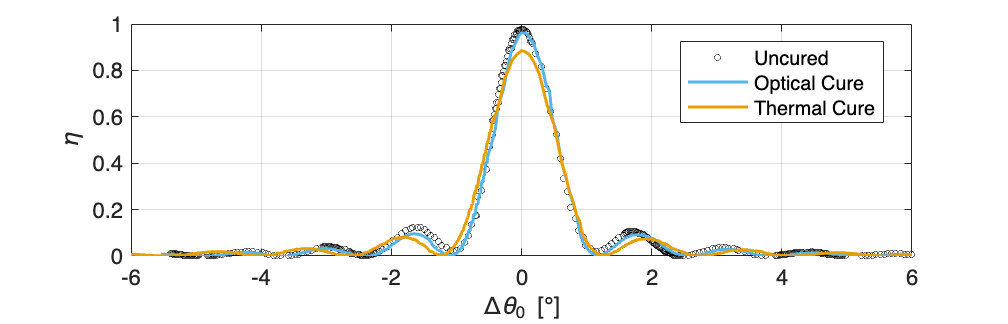


% Plot curves on each other
figure(1)
plot(angleMat{1,1}, detuningMat{1,1},'ko','MarkerSize',3,'LineWidth',0.25); hold on
plot(angleMat{2,1}, detuningMat{2,1},'LineWidth',1.5,'Color',colorBlock(2,:));
plot(angleMat{3,1}, detuningMat{3,1},'LineWidth',1.5,'Color',colorBlock(3,:)); hold off;

% xline(0)
% title(plotTitle);
% subtitle('Unprocessed, optically cured, and thermally cured Bragg curves');
grid on; 
legend('Uncured','Optical Cure','Thermal Cure','Location','best');
xlabel('\Delta\theta_0 [\circ]'); ylabel('\eta');
axis([-6 6 0 1])
% set(gca,'FontSize',16)

% % Now plot drops changes in n1 and L
% n1_vec = [Raw.Data.OUT.CWT.out.n1; Optical.Data.OUT.CWT.out.n1; Thermal.Data.OUT.CWT.out.n1];
% L_vec  = [Raw.Data.OUT.CWT.out.L;  Optical.Data.OUT.CWT.out.L;  Thermal.Data.OUT.CWT.out.L];
% 
% figure(2)
% yyaxis left
% plot([1;2;3],n1_vec.*10^3,'-*','LineStyle','none','MarkerSize',10); grid on; hold on;
% ylabel('Fit RI Contrast (n1\times10^-3)')
% yyaxis right
% plot([1;2;3],L_vec.*10^6,'-^','LineStyle','none','MarkerSize',10); hold off;
% ylabel('Fit Thickness (\mum)')
% legend('n1','L')
% 
set(gca,'FontSize',11)

% Set figure size
% Regular % [x y w h]
set(gcf, 'Units', 'Inches', 'Position', [5, 5, 7.0, 2.25]) % [5, 5, 5.7, 4.7]
xlim([-6 6]); ylim([0 1])

% Save figure
OutputTitle = 'Bragg Curves - Main figure';
print(gcf,OutputTitle,'-dtiff','-r1200');

% Plot Bragg curve on log scale
clear; close all; clc;

fileDir = "/Users/andrewsias_m3p/Library/CloudStorage/OneDrive-UCB-O365/Holography/Experiment Data/Holography Experiments/AS_2024_11_06_02/Thermal Cure/REPORTS/AO-GH1023-1103-S2 E8 Thermal Cure.mat";
B = load(fileDir);

x = B.OUT.DATA.angleVec;
y = B.OUT.DATA.detuningVec;

figure
plot(x,y,'linewidth',2); grid on;
axis([-8 8 0 1]); 
title('Bragg Detuning - Linear Scale');
xlabel('\Delta\theta_0 [\circ]');
ylabel('\eta/\eta_0');
set(gca,'fontsize',16)

figure
semilogy(x,y,'r','LineWidth',2); grid on;
title('Bragg Detuning - Log Scale');
xlabel('\Delta\theta_0 [\circ]');
ylabel('\eta/\eta_0');
set(gca,'fontsize',16)

clear; close all; clc;

tableDir = "/Users/andrewsias_m3p/Library/CloudStorage/OneDrive-UCB-O365/Work/Projects/Collaboration Work/AO - Glassy Holograms with Epoxy/AO-GH1023-1103-S2 Fit Data.xlsx";
T = readtable(tableDir,"VariableNamingRule",'preserve');

figure
boxplot([T.("Raw n1"),T.("OC n1"),T.("TC n1")],{'Raw','Optical Cure','Thermal Cure'}); 
title('Contrast Loss (n_1) with Processing Condition')

grid on; xlabel('Readout Condition'); ylabel('n_1\times10^-3');
set(gca,'FontSize',16)

figure
boxplot([T.("Raw L"),T.("OC L"),T.("TC L")],{'Raw','Optical Cure','Thermal Cure'}); 
title('Thickness Loss (L) with Processing Condition')

grid on; xlabel('Readout Condition'); ylabel('L [\mum]');
set(gca,'FontSize',16)

% Re-plot 2 Bragg curves on top of each other
clear; close all; clc;

% File directories for each .mat file per condition
Raw.fileDir     = "/Users/andrewsias_m3p/Library/CloudStorage/OneDrive-UCB-O365/Holography/Experiment Data/Holography Experiments/AS_2024_12_13_01/Glassy/REPORTS/Glassy Readout at 23 C.mat";
Optical.fileDir = "/Users/andrewsias_m3p/Library/CloudStorage/OneDrive-UCB-O365/Holography/Experiment Data/Holography Experiments/AS_2024_12_13_01/Glassy/REPORTS/Glassy Readout at 65 C.mat";
% Thermal.fileDir = "/Users/andrewsias_m3p/Library/CloudStorage/OneDrive-UCB-O365/Holography/Experiment Data/Holography Experiments/AS_2024_11_06_02/Thermal Cure/REPORTS/AO-GH1023-1103-S2 E8 Thermal Cure.mat";

% Plot title
plotTitle = "Glassy Bragg Curves at 22 and 70 ^{\circ} C";

% Load the data files
Raw.Data     = load(Raw.fileDir); % 22 C
Optical.Data = load(Optical.fileDir); % 70 C
% Thermal.Data = load(Thermal.fileDir);

% Define paper colors
colorBlock = [0                   0                  0                  ; % Black
              0.33725490196078434 0.7058823529411765 0.9137254901960784 ; % Blue
              0.90196078431372550 0.6235294117647059 0.0000000000000000]; % Gold

% Some data re-formatting
angleMat    = {Raw.Data.OUT.DATA.angleVec;
               Optical.Data.OUT.DATA.angleVec};

detuningMat = {Raw.Data.OUT.DATA.detuningVec;
               Optical.Data.OUT.DATA.detuningVec};

% Add readout values to output for referencing
fprintf('Uncured: n1 = %f x 10^-3, L = %f um.\n',Raw.Data.OUT.CWT.out.n1*10^3,Raw.Data.OUT.CWT.out.L*10^6);

Uncured: n1 = 5.409159 x 10^-3, L = 40.914395 um.


fprintf('Optical Cure: n1 = %f x 10^-3, L = %f um.\n',Optical.Data.OUT.CWT.out.n1*10^3,Optical.Data.OUT.CWT.out.L*10^6);

Optical Cure: n1 = 5.574443 x 10^-3, L = 40.346241 um.


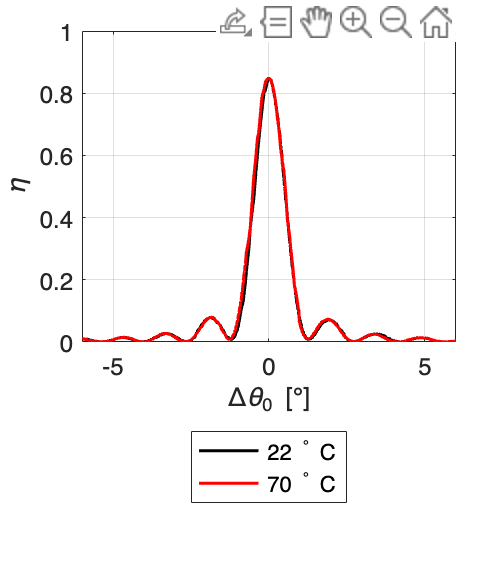


% Plot curves on each other
figure(1)
plot(angleMat{1,1}, detuningMat{1,1},'k','LineWidth',1.5); hold on
plot(angleMat{2,1}, detuningMat{2,1},'r','LineWidth',1.5); hold off;

% xline(0)
% title(plotTitle);
% subtitle('Unprocessed, optically cured, and thermally cured Bragg curves');
grid on; 
legend('22 ^{\circ} C','70 ^{\circ} C','Location','southoutside');
xlabel('\Delta\theta_0 [\circ]'); ylabel('\eta');
axis([-6 6 0 1])
set(gca,'FontSize',12)

% % Now plot drops changes in n1 and L
% n1_vec = [Raw.Data.OUT.CWT.out.n1; Optical.Data.OUT.CWT.out.n1; Thermal.Data.OUT.CWT.out.n1];
% L_vec  = [Raw.Data.OUT.CWT.out.L;  Optical.Data.OUT.CWT.out.L;  Thermal.Data.OUT.CWT.out.L];
% 
% figure(2)
% yyaxis left
% plot([1;2;3],n1_vec.*10^3,'-*','LineStyle','none','MarkerSize',10); grid on; hold on;
% ylabel('Fit RI Contrast (n1\times10^-3)')
% yyaxis right
% plot([1;2;3],L_vec.*10^6,'-^','LineStyle','none','MarkerSize',10); hold off;
% ylabel('Fit Thickness (\mum)')
% legend('n1','L')
% 

% Set figure size
% Regular % [x y w h]
set(gcf, 'Units', 'Inches', 'Position', [5, 5, 3.5, 4]) % [5, 5, 5.7, 4.7]
xlim([-6 6]); ylim([0 1])


% % Save figure
% OutputTitle = 'Bragg Curves - abstract figure';
% print(gcf,OutputTitle,'-dtiff','-r1200');